# SimpleHarmonicOscillatorMovingGliderVideoAnalysis

Imports a video of an oscillating slider attached to springs on an air track, looks for oscillation in pixel values, and finds oscillation frequency. The slider is a dark object. The video captures a partial view of the slider as it arrives in view near the peak of the oscillation.  Each frame is cropped to include only the region of the moving glider. For each frame,  the mean gray scale pixel value and the mean pixel value of a binary image are found. The binary image is obtained with a color selection designed to highlight the dark slider. The binary image is less sensitive to the changes in illuimination and backgrouind as the slider moves. Peaks in the mean binary image value as a function of time are used to determine the oscillation frequency.

*Copyright D. Carlsmith*

### Initialize

Close out any lurking videoplayers, figures, and variables.

uiscopes.close('All'); % close videoplayers
clearvars;% clear variables in workspace
delete(findall(0,'Type','figure'));% clear figures

### Get video data

Set filename of video to analyze and release time and end time (found by scrolling the video). Comment out unneeded lines to select a different file.

vidfile='8cm_Amplitude.mp4';starttime=8;endtime=23;
vidfile='11cm.mp4';starttime=9;endtime=23;
vidfile='14cm_Amplitude.mp4';starttime=9;endtime=23;
vidfile='17cm_Amplitude.mp4';starttime=11;;endtime=26;

Play the video with i[mplay](https://www.mathworks.com/help/images/ref/implay.html). This will open a video player with which one can view the raw (uncropped) video).

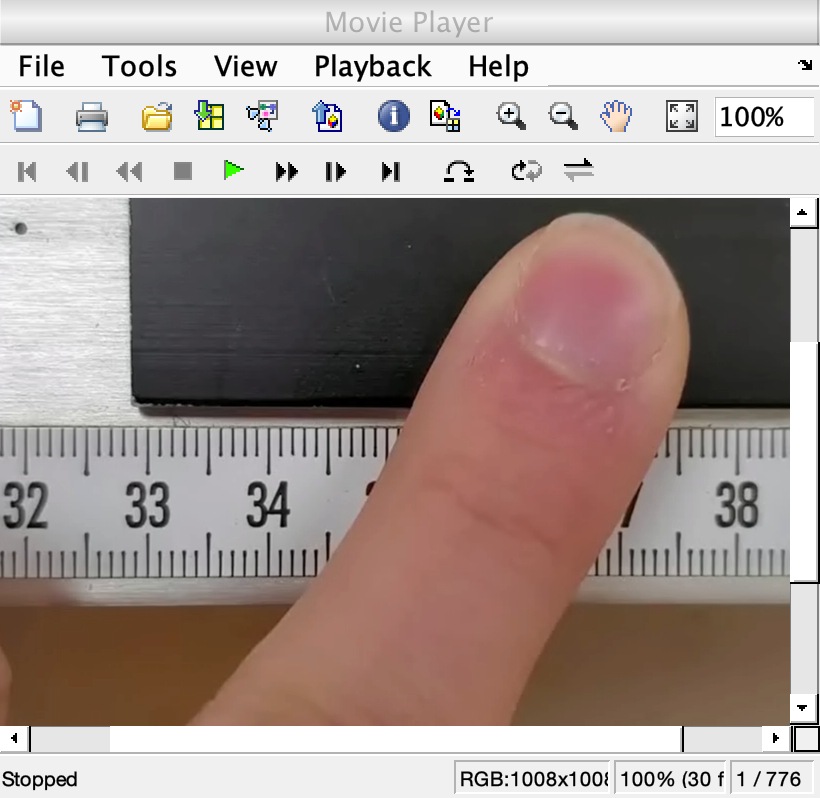

implay(vidfile)

Open video file using [VideorReader](https://www.mathworks.com/help/matlab/ref/videoreader.html) and note frame dimensions, frame rate, and number of frames.

v = VideoReader(vidfile);
nX = v.Width;
nY = v.Height;
v.CurrentTime = 0;
framerate=v.Framerate;
numFrames=v.numframes;

### Process video

Read in entire video frame by frame. A frame/[image](https://www.mathworks.com/help/matlab/ref/image.htm) is a multidimensional array of dimension nX x nY x ncol where nX and nY are the dimensions of the pixel array in an image and ncol =3 colors for an RGB video. The number of rows and columns start at the top left corner of the image. Use the [cat](https://www.mathworks.com/help/matlab/ref/double.cat.html) function to concatenate frames to form an array `video` of dimension nX x nY x ncol x nFrame, and compute mean pixel and mean binary selected pixel values.

Initialize frame counter.

iframe=0;

The beginning of the video shows the slider being dragged by a finger to the point of release. Set starting frame number and ending frame number to keep only free oscillation data after the release. The start and end frame numbers are found from the start and end times hard-wired into the code above.

startframe=starttime*framerate;
endframe=endtime*framerate;

For testing, we could take the first 100 frames of live action after the starting frame. Since a frame is 3-6 megabytes, that limits processing to less than 1 GB of data. 

%endframe=startframe+100-1;

Compute the number of frames to use.

nframe=endframe-startframe+1;

Initialize array to hold mean values of the gray scale images.

meangray=zeros(nframe,1);

Initialize array to hold mean values of the binary images.

meanBW=zeros(nframe,1);

Create array of times starting at the release time.

time=[1:nframe]/framerate;

Loop over frames, read a frame (3d array since RGB) and store it in a 4d-array `video` and the grayscale version in `BW` using [`cat`](https://www.mathworks.com/help/matlab/ref/double.cat.html). while computing the mean grayscale pixel value and the mean binary pixel value.

while hasFrame(v)
    iframe=iframe+1; %frame counter within video
    Frame = readFrame(v);    

Crop each frame to 25 percent of the rows to capture the moving glider region alone.

    Frame=Frame(size(Frame,1)/4:size(Frame,1)/2,:,:,:);    

Create gray scale image.

    gray=rgb2gray(Frame);   

Create a binary image using thresholds to select the dark slider. The selection criteria on each RGB channel were chosen using the [Color Thresholder app](https://www.mathworks.com/help/images/ref/colorthresholder-app.html).

**Try this**: Change the threshold value thres to see the impact.

    I = Frame; 
    thres=250.;
    thres=100.;
    % Define thresholds for channel 1 
    channel1Min = 0.000;
    channel1Max = thres;
    
    % Define thresholds for channel 2 
    channel2Min = 0.000;
    channel2Max = thres;
    
    % Define thresholds for channel 3 
    channel3Min = 0.000;
    channel3Max = thres;
    
    % Create mask based on chosen histogram thresholds
    sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
        (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
        (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
    BW = sliderBW;
    

Initialize arrays to be concatenated and save the first cropped frame.

    if iframe==startframe
            video=Frame;
            BW=sliderBW;
            Frame1=Frame;
            imshow(Frame1)
    end    

Concatenate arrays and compute mean pixel values for each frame.

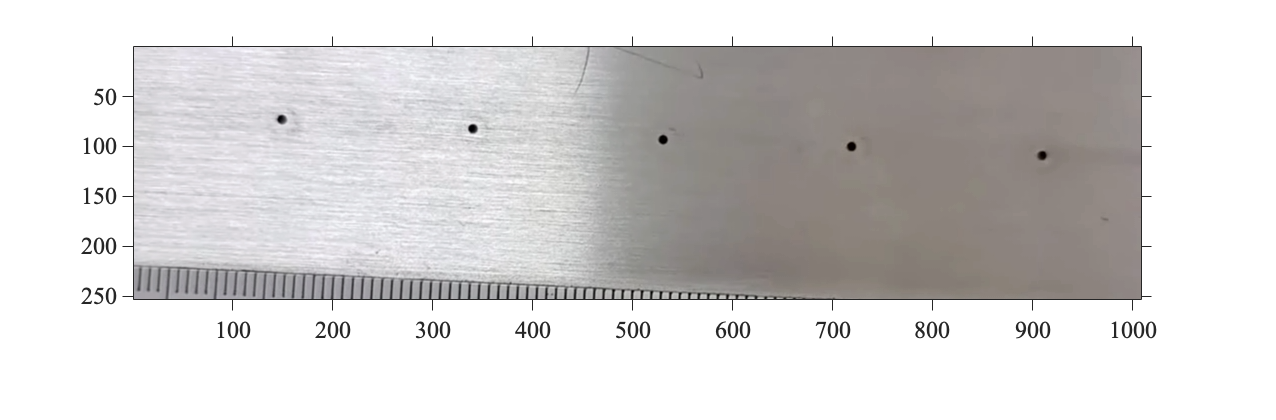

if iframe>=startframe&iframe<=endframe
        video=cat(4,video,Frame);
        BW=cat(3,BW,sliderBW);
        meangray(iframe-startframe+1)=mean(gray,'all');
        meanBW(iframe-startframe+1)=mean(BW,'all');
    end
    
end

Show size of concatenated array.

whos video

  Name         Size                        Bytes  Class    Attributes

  video      253x1008x3x448            342752256  uint8              



### Process mean pixel values over time to find the period of the oscillation.

Plot the mean of the gray scale pixel values.

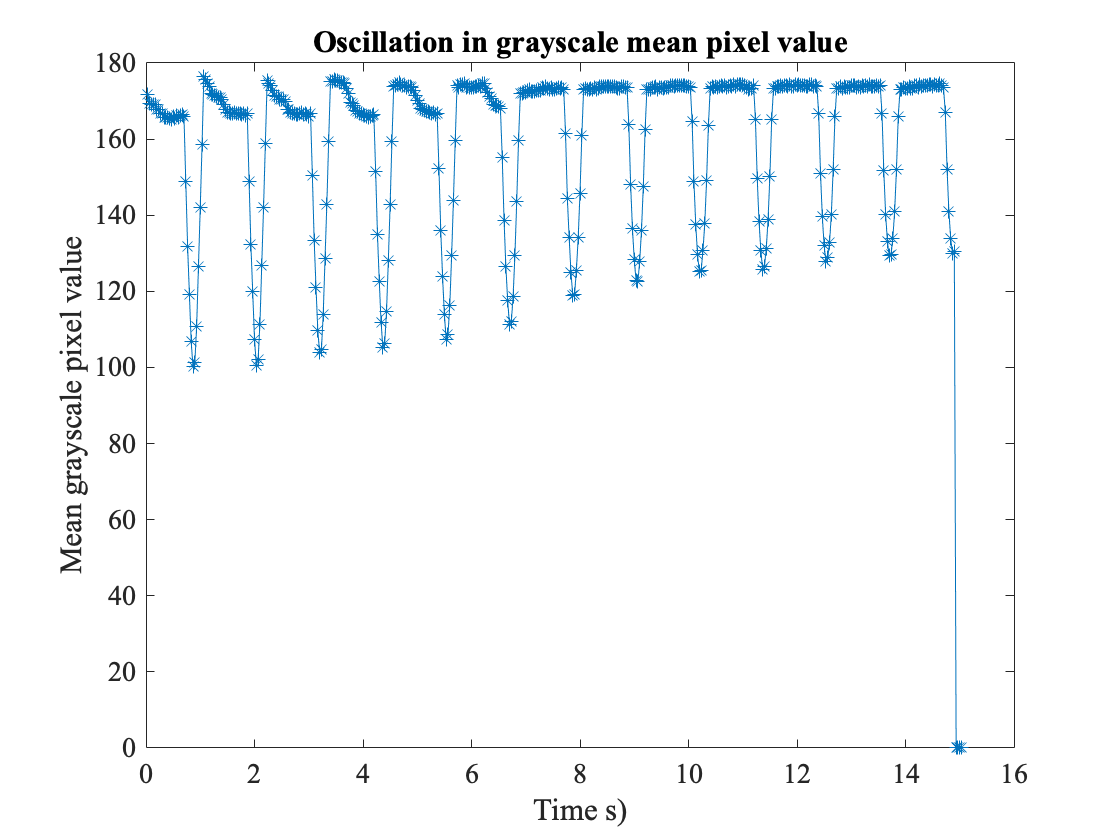

figure
plot(time,meangray,'*-')
xlabel('Time s)');ylabel('Mean grayscale pixel value')
title('Oscillation in grayscale mean pixel value')

We see the mean grayscale pixel value reach a minimum when the black glider reaches a maximum extension, maximally filling the cropped image. When the slider has left the image, the mean grayscale pixel value still changes as the reflected light illumination depends upon glider location.

Plot the mean of the binary pixel values.

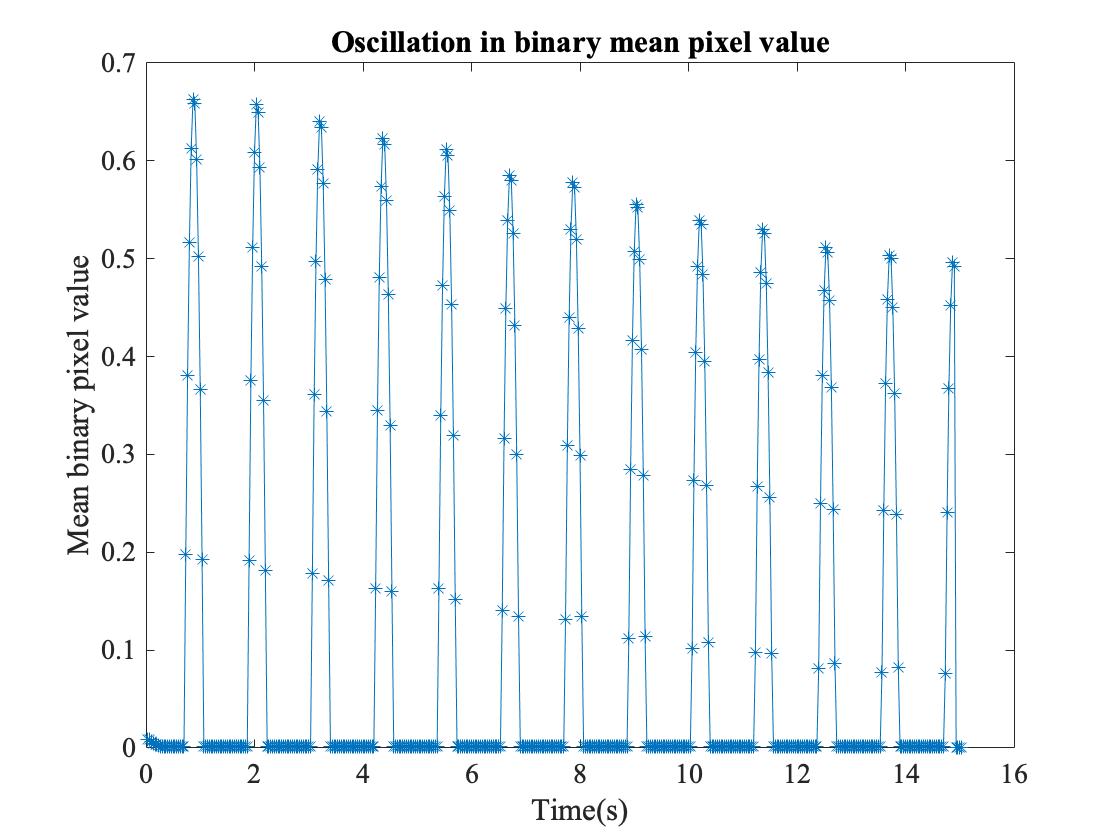

figure
plot(time,meanBW,'*-')
xlabel('Time(s)');ylabel('Mean binary pixel value')
title('Oscillation in binary mean pixel value')

We see the mean binary pixel value, counting dark pixels, reach maxima when the dark glider reaches a maximum extension, maximally filling the cropped image.

Find peaks in the binary pixel values with [findpeaks](https://www.mathworks.com/help/signal/ref/findpeaks.html). Note that the peak prominence is hand selected to exclude noise in the data. Also note that the initial (1-sided) peak will not be found.

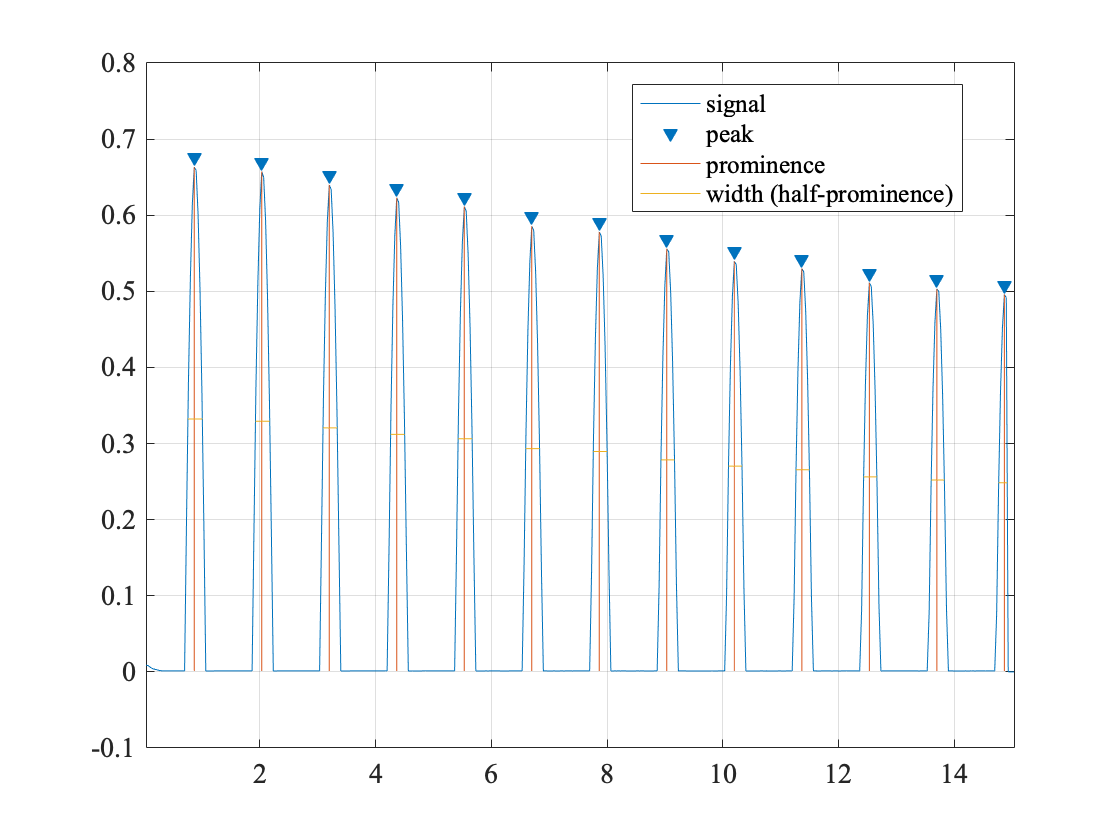

findpeaks(meanBW,time,'MinPeakProminence',0.05,'Annotate','extents')

[pks,locs] = findpeaks(meanBW,time,'MinPeakProminence',0.1)

pks =       0.66314
      0.65749
       0.6399
        0.623
       0.6115
      0.58546
      0.57803
      0.55589
      0.53945
      0.53006


locs =       0.86667       2.0333          3.2       4.3667       5.5333          6.7       7.8667       9.0333         10.2       11.367       12.533         13.7       14.867


Estimate period from the time difference between the first and last peak divided by the number of periods.

npeaks=length(locs);
period = (locs(npeaks)-locs(1))/(npeaks-1)

period =        1.1667


Estimate error from the frame rate. There is a quantization error of $1/\sqrt(12)$ times the time between frames for the first and last frame so treating these as independent, the error is $1/\sqrt(6)$ of the time between frames.

perioderr=1/(sqrt(6)*framerate)

perioderr =      0.013608
